*wersja 23.10.2023*

# Raport z ćwiczenia FRA

**Data: __.__.2023**

**Imię i nazwisko: ___________________________**

Sprawozdanie z ćwiczeń laboratoryjnych powinno składać się z TRZECH części : REZULTATY / ANALIZA I WNIOSKI / ODPOWIEDZI NA PYTANIA (chyba że instrukcja do ćwiczenia określa to inaczej).

## REZULTATY

Zanotuj określone w treści ćwiczenia parametry algorytmów, otrzymane rezultaty, itp. 

Opc. zamieść listę dodatkowych plików dołączonych do sprawozdania (dodatkowe pliki to np. fragmenty kodu, pliki danych otrzymane w trakcie ćwiczenia, itp.) 

**Uwaga - ten interaktywny skrypt jest zautomatyzowany, tzn. wystarczy uruchomić odpowiednie sekcje skryptu aby uzupełnić sprawozdanie (rezultaty).**

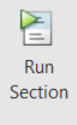

W przyszłych ćwiczeniach zachęcam do tworzenia własnych interaktywnych skryptów, automatyzujących tworzenie sprawozdania. 

**Taki skrypt można szybko skonwertować do pliku PDF (sprawozdania na UPEL oddajemy w formacie PDF)**

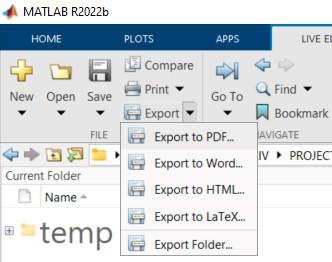

Są dostępne różne tryby zamieszczania rezultatów obliczeń w skrypcie - do ćwiczenia wykorzystujemy "outpul inline", czyli rezultaty wkomponowane w treść skryptu.

Można to zmienić klikając w odpowiednie ikonki z prawej strony edytora:

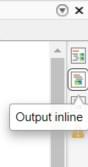

### Część Ia

Utwórz skrypt `przyklad_etap2.m `i uruchom go wg instrukcji podanej w lekcji UPEL.  

Uruchom tą sekcję aby uzupełnić sprawozdanie - rezultaty wykonania skryptu `przyklad_etap2.m`

im = imread('przyklad_etap2_printscreen.jpg');
imshow(im,[])

### Część Ib

Sprawdź działanie klasy `exportPrzyklad.m` – uruchom linia po linii przykład zawarty na początku, w opisie klasy.

Uruchom tą sekcję aby uzupełnić sprawozdanie.

T = readtable("test.txt")

T = 2×2 table
    NrRamki    Rezultat
    _______    ________

       1       0.81472 
       2       0.90579 


### Część Ic

Uruchom skrypt `przyklad_etap3.m` używając nazwy pliku wyjściowego (w kodzie: Zrzut ekranu - zapis do pliku) - "przyklad_etap3_printscreen.jpg"

Uruchom tą sekcję aby uzupełnić sprawozdanie - rezultaty wykonania skryptu `przyklad_etap3.m`

T = readtable("test3.txt");
if isempty(T)
    warning('Nie wyeksportowano żadnych danych w skrypcie "przyklad_etap3.m" ')
end
plot(T.NrRamki,T.Rezultat)
xlabel('nr ramki')
ylabel('suma pikseli')


if exist('exportObj','var')
    warning('Nie usunięto obiektu "exportObj" w skrypcie "przyklad_etap3.m" ')
end

im = imread('przyklad_etap3_printscreen.jpg');
imshow(im,[])

### Część 2a

Uruchom skrypt `testHarness_0.m`

Uruchom tą sekcję aby uzupełnić sprawozdanie - rezultaty wykonania skryptu `testHarness_0.m`

T = readtable("out.txt","Delimiter","=")
if isempty(T)
    warning('Nie wyeksportowano żadnych danych w skrypcie "testHarness_0.m" ')
end

### Część 2b

Sprawdź działanie klasy **myDataSourceVid**`.m` – uruchom linia po linii przykład zawarty na początku, w opisie klasy.

Uruchom tą sekcję aby uzupełnić sprawozdanie.

if ~exist('vidFPS','var')|~exist('nFrames','var')|~exist('imSize','var')
    warning('Prawdopodobnie nie uruchomiono przykładu użycia - brak zmiennej vidFPS lub nFrames lub imSize')
else
    disp(['liczba ramek  = ' num2str(nFrames)])
    disp(['FPS           = ' num2str(vidFPS)])
    disp(['rozdzielczość = ' num2str(imSize)])
end

### Zadanie 3a

Uzupełnij klasę **myDataSourceCam **wg instrukcji do ćwiczenia i przetestuj jej działanie. Pamiętaj o ustawieniu odpowiedniego numeru kamery.

Uruchom tą sekcję aby uzupełnić sprawozdanie.

Poprawne uzupełnienie klasy nie powinno skutkować błędami i ostrzeżeniami poniżej (za to powinien zostać wyświetlony obraz). *Jeśli tak się nie dzieje zamieść odpowiednią informację w sprawozdaniu wraz z własną próbą odkrycia przyczyny problemu.*

try
     parametryImportu        = [];
     parametryImportu.nr     = 1; 
     vid1                    = myDataSourceCam(parametryImportu);    
catch Me    
    disp('Źle zainicjalizowany obiekt kamery - możliwe przyczyny: ')
    disp(' - w zmiennej "obj.vidObj" powinien być obiekt webcam')
    disp(' - numer kamery powinien być większy od zera, i nie większy niż liczba dostępnych kamer ')
    disp(' - lista kamer: ')
    webcamlist    
    error(Me.message)            
end
try
     IM      = vid1.pobierzDane;
     vidFPS  = vid1.vidFPS;
     nFrames = vid1.nFrames;
     imSize  = vid1.imSize;    
     imshow(IM)
catch Me    
    disp('Źle uzupełniony kod metody "pobierzDane" - możliwe przyczyny: ')
    disp(' - metoda nie zwraca obrazu w zmiennej "dataFrame" ')
    error(Me.message)            
end
imSize2     = size(IM);
assert(all(imSize2(1:2)==imSize),"Źle uzupełniony kod metody 'pobierzDane' - rozmiar obrazu nie zgadza się z ustawieniami kamery.")
disp(vid1.test)
clear vid1   

### Zadanie 3b

Uzupełnij klasę **myExportDataVid **wg instrukcji do ćwiczenia.

Uruchom tą sekcję aby uzupełnić sprawozdanie.

Poprawne uzupełnienie klasy nie powinno skutkować błędami i ostrzeżeniami poniżej (za to powinien zostać wyświetlony obraz). *Jeśli tak się nie dzieje zamieść odpowiednią informację w sprawozdaniu wraz z własną próbą odkrycia przyczyny problemu.*

warning off
delete myexport.txt
delete myexport.avi
warning on
RGB                          = imread('ngc6543a.jpg');
parametryEksportu            = [];
parametryEksportu.nazwapliku = 'myexport.avi';
exportObj                    = myExportDataVid(parametryEksportu);    

---=== myExportDataVid ===---
Nazwa pliku wyjściowego AVI  =       myexport.avi
Nazwa pliku wyjściowego TXT  =       myexport.txt



dane_do_eksportu             = [];
dane_do_eksportu.iter        = 1; 
dane_do_eksportu.outVidData  = RGB;
exportObj.eksportujDane(dane_do_eksportu);
disp(exportObj.test)

     0



vidtestobj = exportObj.vidObj;
delete(exportObj)  
try
    writeVideo(vidtestobj, RGB);
    warning("myExportDataVid nie został uzupełniony poprawnie :")
    warning(" -  prawdopodobnie nie zamknięto pliku video w metodzie 'delete'")    
catch Me
end
if ~exist(parametryEksportu.nazwapliku,"file")
    warning("myExportDataVid nie został uzupełniony poprawnie - brak pliku wyjściowego video")
end
try
    vidtest = VideoReader(parametryEksportu.nazwapliku);
    im      = vidtest.readFrame;
    imshow(im)
catch Me
    warning("myExportDataVid nie został uzupełniony poprawnie :")
    warning(" - prawdopodobnie nie zapisano żadnej ramki do pliku video")
    disp(Me)
end
clear vidtest


### Zadanie 3c

Uzupełnij kod w skrypcie **testHarness_1.m **wg instrukcji do ćwiczenia.

Uruchom tą sekcję aby uzupełnić sprawozdanie.

Poprawne uzupełnienie kodu nie powinno skutkować błędami i ostrzeżeniami poniżej (za to powinien zostać wyświetlony obraz).

testHarness_1

---=== myDataSourceCam ===---
Dane źródła video:       
> numer kamery    = 1
> liczba ramek    = Inf
> FPS             = Inf
> rozdzielczość   = 720x1280
---=== myAlgorithmTemplate ===---
---=== myExportDataVid ===---
Nazwa pliku wyjściowego AVI  =       test_harness_1.avi
Nazwa pliku wyjściowego TXT  =       test_harness_1.txt
---=== myVisualization0 ===---


Początek przetwarzania


if exist(parametryEksportu.nazwapliku,"file")
    vidtest = VideoReader(parametryEksportu.nazwapliku);
    imtab = [];
    for i=1:4
        imtab(:,:,:,i)      = vidtest.readFrame;
    end
    clear vidtest
    montage(imtab/255)
end
T = readtable(strrep(parametryEksportu.nazwapliku,'.avi','.txt'),"Delimiter",",")
if isempty(T)
    warning('Nie wyeksportowano żadnych danych w skrypcie "testHarness_1.m" ')
end
disp(parametryEksportu.nazwapliku)

### Zadanie 3d

Uzupełnij poniższy kod i uruchom tą sekcję:

T = readtable(strrep(parametryEksportu.nazwapliku,'.avi','.txt'),"Delimiter",",");

%ts = ______________;   % wybór z tabeli T kolumny zwierającej timestamp
%dts = ________;        % wyznaczenie różnicy czasu między ramkami (pomoc -> doc diff)
%FPS = ___________;     % wyznaczenie FPS (użycie f. median na wektorze różnic czasu)

plot(dts)              % wyświetlenie różnic czasu pomiędzy ramkami
grid on
xlabel('nr ramki')
ylabel('różnica czasu [ms]')
title(['FPS = ' num2str(FPS)])

Czy akwizycja danych jest stabilna (czas akwizycji ramek jest podobny)? 

## ANALIZA i WNIOSKI

W tym ćwiczeniu jako sprawozdanie oddajemy wygenerowany z tego skryptu plik PDF z rezultatami. Upewnij się, że w wygenerowanym pliku PDF są wszystkie rezultaty z poprzednich sekcji skryptu oraz odpowiedzi na pytania poniżej.

## ODPOWIEDZI NA PYTANIA

1) Wymień i krótko uzasadnij 3 elementy ćwiczenia, które zwróciły Twoją uwagę lub są Twoim zdaniem ważne.

    1. Obiektowe podejście do przetwarzania danych w MATLABIE

    2. Dobrze przygotowane skrypty z czytelną dokumentacją

    3. MATLAB pozwala na utworzenie własnych klas obsługujących wejścia/wyjścia i przetwarzanie obrazów/filmów.

2) Wymień i krótko uzasadnij 2 rzeczy z ćwiczenia, które były dla Ciebie trudne. Przykładowo - w przypadku gdy potrzebna była podpowiedź (skrypt "solution") opisz krótko co było dla Ciebie niezrozumiałe w zadaniu i dlaczego  potrzebowałeś/potrzebowałaś podpowiedzi.

    1.

    2.

3) Zadaj 1 pytanie związane z tym ćwiczeniem (np. co jest dla Ciebie niezrozumiałe lub co chciałbyś/chciałabyś się jeszcze dowiedzieć).

    1.